## Open Methods: The Newton-Raphson Method

In this livescript, you will learn how

- The Newton-Raphson method works

- To write a piece of code that implements the method

Again, we'll be considering the problem


$$f(x)=ax^{2}+(1-a)x=0$$


*Equation 1.*

The Newton-Raphson method works by estimating the function using its first order Taylor series expansion


$$f(x)=f(x_{i})+f'(x_{i})(x-x_{i})$$


i.e. the tangent curve to the graph at the point $x_{i}$.

(a)        For $a=9$, determine the tangent curve to Eq. (1) for an initial guess of $x=0.6$.

(b)        Plot Eq. (1) as well as the tangent curve you determined in part (a).

(c)        Using the tangent curve, approximate the root $x_{r}$ of Eq. (1).

(d)        Set $x_{1}=x_{r}$ and repeat this process once.

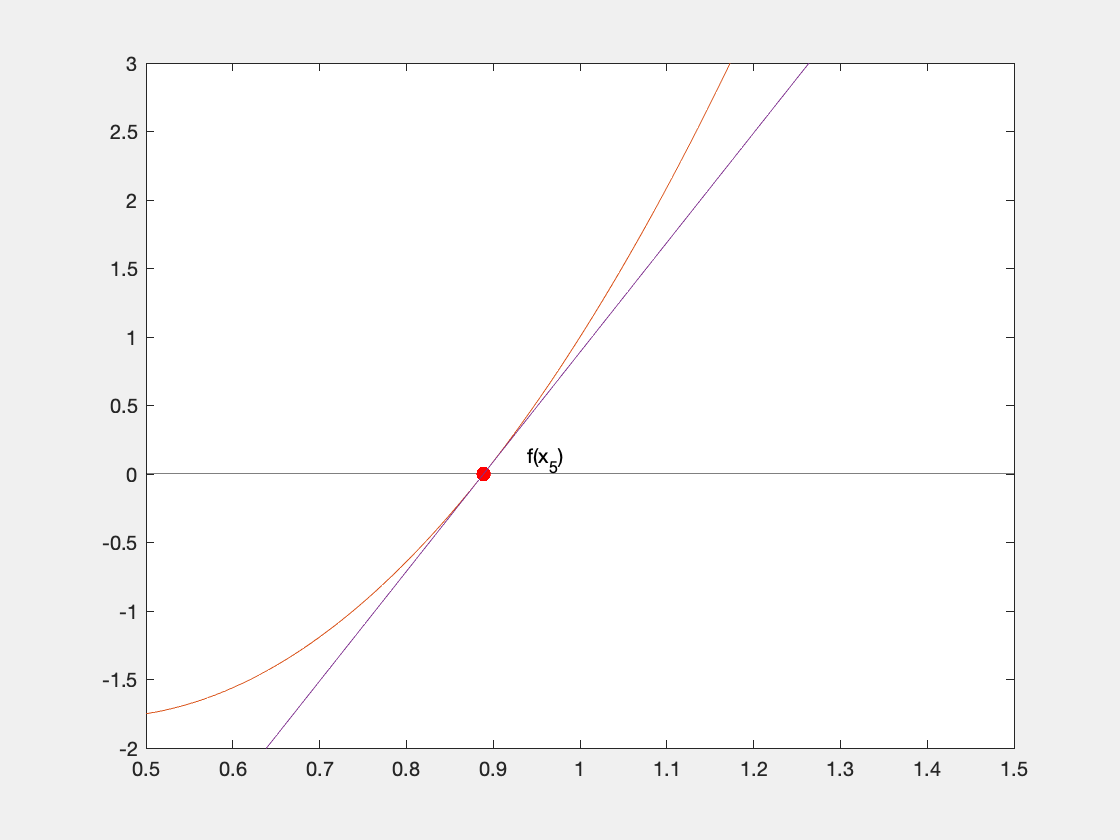

To graphically see how the Newton-Raphson method works, you can run the function $\texttt{newton\_raphson\_example}$

newton_raphson_example()

The basis of this code, without all the graphics, is 

(b)        Run $\texttt{newton\_raphson\_solver}$ and check the outputs with your results in (a).

%%%%%%%%%%%%%%%%%%%%%%%%%
% newton_raphson_solver %
%%%%%%%%%%%%%%%%%%%%%%%%%

a = 9;
f = @(x) a*x.^2+(1-a)*x;
dfdx = @(x) 1-a+2*a*x;           

x = 0.6;                          % Initial Condition
tol = 10^-10;                      % Tolerance of 10e-6
max_iter = 100;                   % This line is prevents the method from iterating in the case it diverges
i = 1;
while abs(f(x))>tol && i<max_iter
    
    x = x - f(x)/dfdx(x);
    i = i+1;
    fprintf('%11.10f\n',x)

end

1.1571428571
0.9393732103
0.8914636702
0.8888963041
0.8888888890
0.8888888889


(c)    In the livescript *ENGR20005_Workshop2p2.mlx*, it was shown that there are certain values of $a$ and certain roots that are difficult to find using the fixed point iteration scheme.  Try finding those roots using Newton Raphson method.  For example, let $a=3.2$ and try to find the root at $x=0.6875$ starting with a guess of $x=0.6$ using the Newton Raphson method.  Can you also find the root at $x=0$?